**Método de aproximación lineal**

**EJERCICIO 1.5**

¿Cuál es el número de Euler e? Probablemente recuerdes usar este número a menudo en Cálculo y Ecuaciones Diferenciales. ¿Conoces la aproximación decimal para este número? Además, ¿hay una manera de aproximar algo como

√e =e^0.5 ó e^−1 sin tener acceso a la expansión decimal completa? Para todas las preguntas a continuación, trabajemos con la función f(x) =e^x.

• La función g(x) = 1 coincide exactamente con f(x) = e^x en el punto x = 0, ya que f(0) = e^0 = 1. Además, si x está muy, muy cerca de 0, entonces las funciones f(x) y g(x) están muy cerca entre sí. Por lo tanto, podríamos decir que 

g(x) = 1 es una aproximación de la función f(x) = e^x para valores de x muy, muy cerca de x = 0. Sin embargo, es probablemente bastante claro que esta es una aproximación horrible para cualquier x un poco alejado de x = 0.

Construye un mejor aproximación. ¿Qué pasa si insistimos en que nuestra aproximación g(x) coincida exactamente con f(x) = e^x en x = 0 y TAMBIÉN tenga exactamente la misma primera derivada que f(x) en x = 0?

– ¿Cuál es la primera derivada de f(x)?

– ¿Cuál es f′(0)?

– Usa la forma punto-pendiente de una línea para escribir la ecuación de la función g(x) que pasa por el punto (0, f(0)) y tiene pendiente f′(0). Recuerda que la forma punto-pendiente de una línea es y = f(x0)+m(x−x0). En este caso, estamos tomando x0 = 0, por lo que estamos usando la fórmula g(x) = f(0) + f′(0)(x − 0) para obtener la ecuación de la línea.

– Escribe código MATLAB para construir un gráfico similar a la Figura 1. Este gráfico muestra f(x) = e^x, nuestra primera aproximacióng(x) = 1 y nuestra segunda aproximación g(x) = 1 + x.

**SOLUCIÓN:**

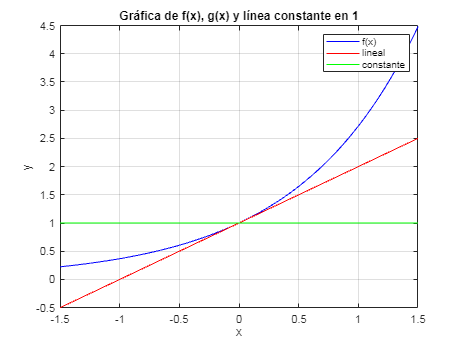

syms x; % Declarar variable simbólica x
f(x) = exp(x);
df = diff(f);
x_min = -1.5; % Límite inferior de x
x_max = 1.5;
x_vals = linspace(x_min, x_max, 100);
df_en_0 = subs(df, x, 0);
m = df_en_0;
g(x) = m*(x - 0) + 1;
y_vals_f = subs(f, x, x_vals);
y_vals_g = subs(g, x, x_vals);
y_constante = ones(size(x_vals));
plot(x_vals, y_vals_f, 'b', x_vals, y_vals_g, 'r', x_vals, y_constante, 'g');
xlabel('x');
ylabel('y');
title('Gráfica de f(x), g(x) y línea constante en 1');
legend('f(x)', 'lineal', 'constante');
grid on;

**EJERCICIO 1.6**

Extendamos la idea del problema anterior a aproximaciones mucho mejores de la función f(x) = e^x. Construyamos una función g(x) que coincida exactamente con f(x) en x = 0, tenga exactamente la misma primera derivada que f(x) en x = 0, Y tenga exactamente la misma segunda derivada que f(x) en x = 0. Para hacer esto, usaremos una función cuadrática. Para una aproximación cuadrática de una función, simplemente tomamos una extensión ligera de la forma punto-pendiente de una línea y usamos la ecuación y = f(x0)+f′(x0)(x−x0)+ f′′(x0)/2 (x−x0)^2. En este caso, estamos usando x0 = 0, por lo que la función de aproximación cuadrática se ve como y = f(0) + f′(0)x + f′′(0)/2 x^2.

• Encuentra la aproximaci´on cuadr´atica para f(x) = e^x.

• ¿Cómo sabes que esta función coincide con f(x) en todas las formas descritas anteriormente en x = 0?

• Añade tu nueva función al gráfico que creaste en el problema anterior.

**SOLUCIÓN:**

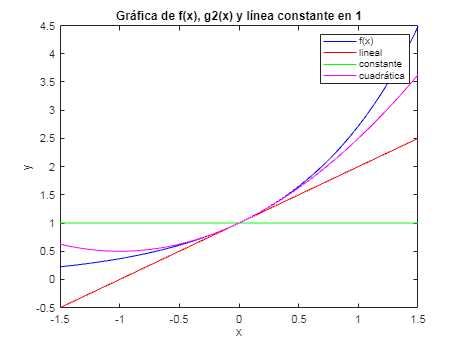

ddf = diff(df);
ddf_en_0 = subs(ddf, x, 0);
g2(x)=1+df_en_0*x+((ddf_en_0)/2)*x^2;
y_vals_g2 = subs(g2, x, x_vals);
plot(x_vals, y_vals_f, 'b', x_vals, y_vals_g, 'r', x_vals, y_constante, 'g',x_vals, y_vals_g2, 'm');
xlabel('x');
ylabel('y');
title('Gráfica de f(x), g2(x) y línea constante en 1');
legend('f(x)', 'lineal', 'constante','cuadrática');

¡Sigamos adelante! A continuación, hagamos una aproximación cúbica. Una aproximación cúbica toma la forma y = f(x0)+f′(0)(x−x0)+ f′′(0)/2 (x−x0)^2+ f′′′(0)/3! (x − x0)^3.

• Encuentra la aproximación cúbica para f(x) = e^x.

• ¿Cómo sabemos que esta función coincide con las primeras, segundas y terceras derivadas de f(x) en x = 0?

• Añade tu función al gráfico.

• Haz una pausa y piensa: ¿Cuál es el trato con el 3! en el término cúbico?

Es tu turno: Construye las siguientes aproximaciones de f(x) = e^x en x = 0. Añade estos gráficos al que hemos estado construyendo todo el tiempo.

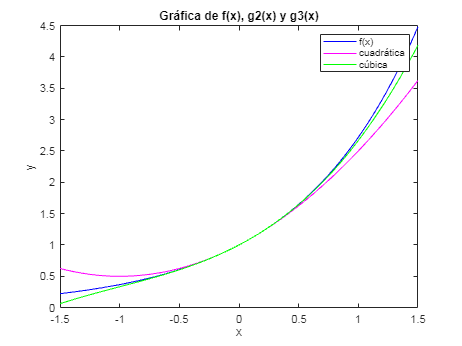

dddf = diff(ddf);
dddf_en_0 = subs(dddf, x, 0);
g3(x)=1+df_en_0*x+((ddf_en_0)/2)*x^2+((dddf_en_0)/6)*x^3;
y_vals_g3 = subs(g3, x, x_vals);
plot(x_vals, y_vals_f, 'b',x_vals, y_vals_g2, 'm',x_vals, y_vals_g3, 'g');
xlabel('x');
ylabel('y');
title('Gráfica de f(x), g2(x) y g3(x)');
legend('f(x)', 'cuadrática','cúbica');

**EJERCICIO 1.7**

Podemos obtener una expansión decimal de e bastante fácil: e ≈ 2.718281828459045. En MATLAB, simplemente escribe exp(1), lo que evaluará f(x) = e^x en x = 1 (y por lo tanto te dará un valor para e^1 = e). Construimos nuestras aproximaciones en los problemas anteriores centradas en x = 0, y x = 1 no está demasiado lejos de x = 0, así que quizás podamos obtener una buena aproximación con las funciones que ya hemos construido. Completa la siguiente tabla para ver cómo nos fue con nuestras aproximaciones.

**SOLUCIÓN:**

% Valores en x=1
c_en_1= 1

c_en_1 = 1

g_en_1 = subs(g, x, 1)

$$g\_en\_1(x) = 2$$

g2_en_1 = vpa(subs(g2, x, 1))

$$g2\_en\_1(x) = 2.5$$

g3_en_1 = vpa(subs(g3, x, 1))

$$g3\_en\_1(x) = 2.6666666666666666666666666666667$$

ddddf = diff(dddf);
ddddf_en_0 = subs(ddddf, x, 0);
g4(x)=1+df_en_0*x+((ddf_en_0)/2)*x^2+(((dddf_en_0)/6)*x^3)+(((ddddf_en_0)/24)*x^4);
g4_en_1 = vpa(subs(g4, x, 1))

$$g4\_en\_1(x) = 2.7083333333333333333333333333333$$

dddddf = diff(ddddf);
dddddf_en_0 = subs(dddddf, x, 0);
g5(x)=1+df_en_0*x+((ddf_en_0)/2)*x^2+(((dddf_en_0)/6)*x^3)+(((ddddf_en_0)/24)*x^4)+(((dddddf_en_0)/120)*x^5);
g5_en_1 = vpa(subs(g5, x, 1))

$$g5\_en\_1(x) = 2.7166666666666666666666666666667$$

%Error absoluto 
e=exp(1);
errcons=e-1

errcons = 1.7183

errlin=e-2

errlin = 0.7183

errcuad=vpa(e-g2_en_1)

$$errcuad(x) = 0.21828182845904509079559829842765$$

errcubi= vpa(e-g3_en_1)

$$errcubi(x) = 0.051615161792378424128931631760982$$

errcuart= vpa(e-g4_en_1)

$$errcuart(x) = 0.0099484951257117574622649650943155$$

err1quin= vpa(e-g5_en_1)

$$err1quin(x) = 0.0016151617923784241289316317609822$$

**EJERCICIO 1.8**

Utiliza las funciones que has construido para aproximar √e = e^0.5. Verifica la precisión de tu respuesta usando MATLAB: exp(0.5).

**SOLUCIÓN:**

raize=exp(0.5)

raize = 1.6487

vpa(sqrt(g5_en_1))

$$ans(x) = 1.6482313753434821283961684973201$$

**EJERCICIO 1.9**

Utiliza las funciones que has construido para aproximar 1/e = e^−1. Verifica la precisión de tu respuesta usando MATLAB: exp(-1).

**SOLUCIÓN:**

euler_1=exp(-1)

euler_1 = 0.3679

1/(g5_en_1)

$$ans(x) = 0.36809815950920245398773006134969$$

**EJERCICIO 1.10**

Verifica a partir de tu trabajo anterior que la Serie de Taylor centrada en x0 = 0 (es decir, la Serie de Maclaurin) para f(x) = e^x es de hecho e^x = 1 + x + x^2/2 + x^3/3! + x^4/4! + x^5/5!+ · · · 

**SOLUCIÓN:**

% 1 Definir la función
syms x 
f(x)= exp(x)

$$f(x) = {\mathrm{e}}^{x}$$

% 2 y 3 Derivadas y serie
%--------- Entrada
x0=0;
f

$$f(x) = {\mathrm{e}}^{x}$$

% n para este caso, no sabemos n 
error = 10e-5;
%--------- fin Entrada
%--------- Paso 1
sum=0; 
n=9; % el máximo de iteraciones 
df(x)=f;
%--------- Paso 2
for i=1:n
    df(x)=diff(df,x);
    sum=sum+subs(df,x,x0)*(x-x0)^i/factorial(i);
end
sum

$$sum(x) = \frac{x^{9}}{362880}+\frac{x^{8}}{40320}+\frac{x^{7}}{5040}+\frac{x^{6}}{720}+\frac{x^{5}}{120}+\frac{x^{4}}{24}+\frac{x^{3}}{6}+\frac{x^{2}}{2}+x$$